# `Μαθηματικά ΙΙ`

## **Εξαμηνιαία εργασία 2 **

# [ΠΡΟΚΟΠΙΟΣ] [ΚΑΜΑΤΣΟΣ], Α.Μ. 1072586

Αντικαταστήστε τη λέξη όνομα με το δικό σας, αντίστοιχα με τη λέξη επώνυμο όπως και με τον Α.Μ. 

Η εικόνα της f στο (0,0) είναι 0 και προκύπτει από τον πάνω κλάδο. Πέρνοντας τα όρια στο 0 προς τα δεξιά και αριστερά από τον δεύτερο και πρώτο κλάδο αντίστοιχα προκύπτουν διαφορετικές τιμές 1 και 0 αντίστοιχα.

Επομένως η συνάρτηση είναι μη συνεχής στο σημείο (0,0) καθώς δεν υπάρχει το όριο της f στο (0,0).

# Ερώτημα 1.1

[Για την επίλυση του παρόντος ερωτήματος όπως και των υπολοίπων χρησιμοποιήστε την επιλογή text για να γράψετε κείμενο ή μαθηματικές εκφράσεις όπου θεωρείτε ότι χρειάζεται. Μαθηματικές εκφράσεις όπως $\frac{x+y}{x^2 + y^2}$ τις εισάγετε από το tab insert $\rightarrow$ Equation (Σ or \latex)]

[Αντιγράψτε τα παραπάνω για όλα τα ερωτήματα]

# Ερώτημα 1.1 

syms x y LocMax LocMin Saddle Unknown real
f0(x,y) = 6 - x^2 - 4*y^2 

$$f0(x, y) = -x^{2}-4\,y^{2}+6$$

%x = -2:2; y = -1:1;
grad_f0 = gradient(f0, [x y])'

$$grad\_f0(x, y) = \left(\begin{array}{cc} -2\,x & -8\,y \end{array}\right)$$

hess = hessian(f0, [x y]); H = hess(x,y)

$$H = \left(\begin{array}{cc} -2 & 0\\ 0 & -8 \end{array}\right)$$

LPMD(x,y) = [H(1,1), det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} -2 & 16 \end{array}\right)$$

c = solve(grad_f0 ==[0 0], [x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M = [c.x c.y], m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

m = 1

disp('x y f0 LPMD Type')

x y f0 LPMD Type


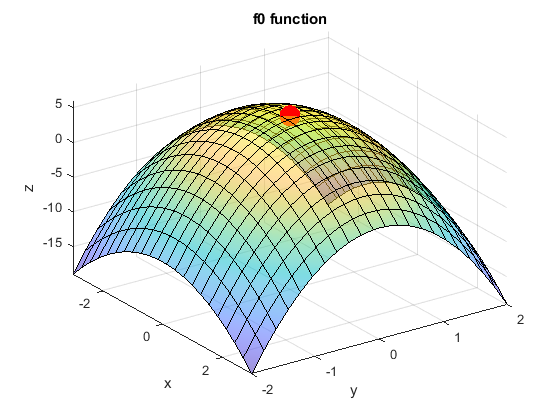

for k = 1:m
    xp = M(k,1); yp=M(k,2); P = [xp yp]; L = LPMD(xp, yp);
    if L(1)>0 && L(2)>0  
        T=LocMin;
    elseif L(1)<0 && L(2)>0 
        T=LocMax;
    else 
        T=Unknown;
    end
end
figure 
fsurf(f0(x,y), [-3 3 -2 2], 'MeshDensity', 22); hold on 
plot3(c.x, c.y, f0(c.x, c.y), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 15)
xlabel('x'); ylabel('y'); zlabel('z');
title('f0 function'); alpha 0.5
view(55, 35)

syms x y LocMax LocMin Saddle Unknown real
f1(x, y)=x*y*exp(-x-y)

$$f1(x, y) = x\,y\,{\mathrm{e}}^{-x-y}$$

grad_f1=gradient(f1,[x y])'

$$grad\_f1(x, y) = \left(\begin{array}{cc} y\,{\mathrm{e}}^{-x-y}-x\,y\,{\mathrm{e}}^{-x-y} & x\,{\mathrm{e}}^{-x-y}-x\,y\,{\mathrm{e}}^{-x-y} \end{array}\right)$$

hess=hessian(f1,[x y]); H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} x\,y\,{\mathrm{e}}^{-x-y}-2\,y\,{\mathrm{e}}^{-x-y} & \sigma_{1}\\ \sigma_{1} & x\,y\,{\mathrm{e}}^{-x-y}-2\,x\,{\mathrm{e}}^{-x-y} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x-y}-x\,{\mathrm{e}}^{-x-y}-y\,{\mathrm{e}}^{-x-y}+x\,y\,{\mathrm{e}}^{-x-y} \end{array}$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} x\,y\,{\mathrm{e}}^{-x-y}-2\,y\,{\mathrm{e}}^{-x-y} & -{\mathrm{e}}^{-2\,x-2\,y}\,\left(x^{2}-2\,x+y^{2}-2\,y+1\right) \end{array}\right)$$

c=solve(grad_f1==[0,0],[x,y])

c = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0\\ 1 & 1 \end{array}\right)$$

m = 2

disp('x y f1 LPMD Type')

x y f1 LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp, yp);
    if L(1)>0 && L(2)>0
        T = LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f1(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & -1 & \mathrm{Unknown} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 1 & 1 & {\mathrm{e}}^{-2} & -{\mathrm{e}}^{-2} & {\mathrm{e}}^{-4} & \mathrm{LocMax} \end{array}\right)$$

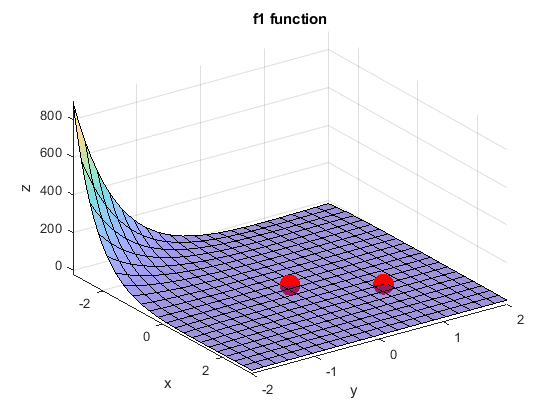

figure
fsurf(f1(x,y), [-3 3 -2 2], 'MeshDensity',22); hold on
plot3(c.x, c.y, f1(c.x, c.y), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 15)
xlabel('x'); ylabel('y'); zlabel('z')
title('f1 function'); alpha 0.5
view(55,35)







syms x y LocMax LocMin Saddle Unknown real
f2(x, y)=(4*x - 1 )^2 + (2*y + 4)^2 +1

$$f2(x, y) = {\left(4\,x-1\right)}^{2}+{\left(2\,y+4\right)}^{2}+1$$

grad_f2=gradient(f2,[x y])'

$$grad\_f2(x, y) = \left(\begin{array}{cc} 32\,x-8 & 8\,y+16 \end{array}\right)$$

hess=hessian(f2,[x y]); H=hess(x,y)

$$H = \left(\begin{array}{cc} 32 & 0\\ 0 & 8 \end{array}\right)$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} 32 & 256 \end{array}\right)$$

c=solve(grad_f2==[0,0],[x,y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} \frac{1}{4} & -2 \end{array}\right)$$

m = 1

disp('x y f2 LPMD Type')

x y f2 LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp, yp);
    if L(1)>0 && L(2)>0
        T = LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f2(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} \frac{1}{4} & -2 & 1 & 32 & 256 & \mathrm{LocMin} \end{array}\right)$$

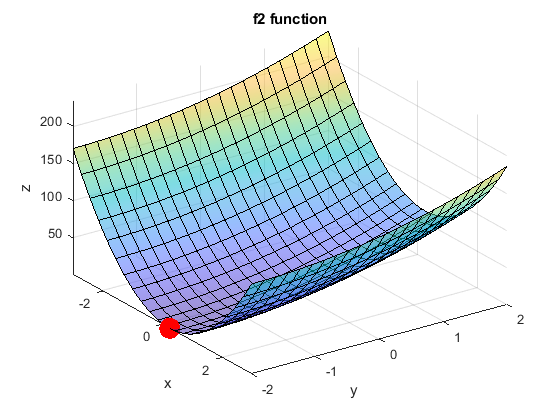

figure
fsurf(f2(x,y), [-3 3 -2 2], 'MeshDensity',22); hold on
plot3(c.x, c.y, f2(c.x, c.y), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 15)
xlabel('x'); ylabel('y'); zlabel('z')
title('f2 function'); alpha 0.5
view(55,35)







syms x y LocMax LocMin Saddle Unknown real
f5(x,y)=2*x*y*exp(-x^2-y^2)

$$f5(x, y) = 2\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

grad_f5=gradient(f5,[x y])'

$$grad\_f5(x, y) = \left(\begin{array}{cc} 2\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}-4\,x^{2}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}} & 2\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}-4\,x\,y^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}} \end{array}\right)$$

hess=hessian(f5, [x,y]); H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} 8\,x^{3}\,y\,\sigma_{2}-12\,x\,y\,\sigma_{2} & \sigma_{1}\\ \sigma_{1} & 8\,x\,y^{3}\,\sigma_{2}-12\,x\,y\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\sigma_{2}-4\,x^{2}\,\sigma_{2}-4\,y^{2}\,\sigma_{2}+8\,x^{2}\,y^{2}\,\sigma_{2}\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

LPMD(x,y)=[H(1,1), det(H)]

$$LPMD(x, y) = \begin{array}{l} \left(\begin{array}{cc} 8\,x^{3}\,y\,\sigma_{1}-12\,x\,y\,\sigma_{1} & -4\,{\mathrm{e}}^{-2\,x^{2}-2\,y^{2}}\,\left(8\,x^{4}\,y^{2}+4\,x^{4}+8\,x^{2}\,y^{4}-20\,x^{2}\,y^{2}-4\,x^{2}+4\,y^{4}-4\,y^{2}+1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

c=solve(grad_f5==[0 0], [x y])

c = struct with fields:
    x: [5×1 sym]
    y: [5×1 sym]


M = [c.x c.y], m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0\\ -\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} \end{array}\right)$$

m = 5

disp('x y f5 LPMD Type')

x y f5 LPMD Type


for k = 1:m
    xp = M(k,1); yp= M(k,2); P = [xp yp]; L = LPMD(xp , yp);
    if L(1)>0 && L(2)>0
        T=LocMin
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f5(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & -4 & \mathrm{Unknown} \end{array}\right)$$

$$\left(\begin{array}{cccccc} -\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & {\mathrm{e}}^{-1} & -4\,{\mathrm{e}}^{-1} & 16\,{\mathrm{e}}^{-2} & \mathrm{LocMax} \end{array}\right)$$

$$T = \mathrm{LocMin}$$

$$\left(\begin{array}{cccccc} \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2} & -{\mathrm{e}}^{-1} & 4\,{\mathrm{e}}^{-1} & 16\,{\mathrm{e}}^{-2} & \mathrm{LocMin} \end{array}\right)$$

$$T = \mathrm{LocMin}$$

$$\left(\begin{array}{cccccc} -\frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & -{\mathrm{e}}^{-1} & 4\,{\mathrm{e}}^{-1} & 16\,{\mathrm{e}}^{-2} & \mathrm{LocMin} \end{array}\right)$$

$$\left(\begin{array}{cccccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & {\mathrm{e}}^{-1} & -4\,{\mathrm{e}}^{-1} & 16\,{\mathrm{e}}^{-2} & \mathrm{LocMax} \end{array}\right)$$

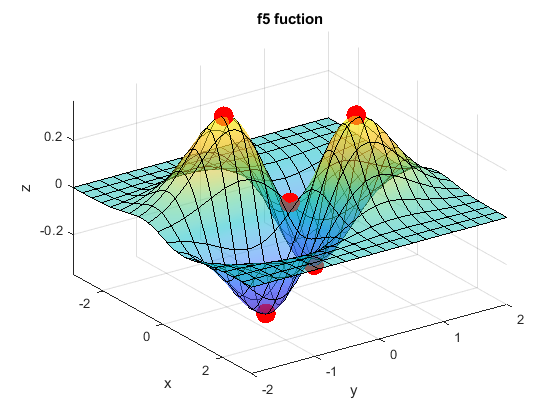

figure
fsurf(f5(x,y), [-3 3 -2 2], 'MeshDensity', 20); hold on
plot3(c.x, c.y, f5(c.x,c.y), 'ro', 'MarkerFaceColor', 'r',"MarkerSize",14 )
xlabel('x'); ylabel('y'); zlabel('z')
title('f5 fuction'); alpha 0.5
view(55,35)



syms x y LocMax LocMin Saddle Unknown real
f6(x,y)= x^2 + x*y^2 - 2*x + 1

$$f6(x, y) = x^{2}+x\,y^{2}-2\,x+1$$

grad_f6=gradient(f6,[x y])'

$$grad\_f6(x, y) = \left(\begin{array}{cc} y^{2}+2\,x-2 & 2\,x\,y \end{array}\right)$$

hess=hessian(f6, [x,y]); H=hess(x,y)

$$H = \left(\begin{array}{cc} 2 & 2\,y\\ 2\,y & 2\,x \end{array}\right)$$

LPMD(x,y)=[H(1,1), det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} 2 & 4\,x-4\,y^{2} \end{array}\right)$$

c=solve(grad_f6==[0 0], [x y])

c = struct with fields:
    x: [3×1 sym]
    y: [3×1 sym]


M = [c.x c.y], m=size(M,1)

$$M = \left(\begin{array}{cc} 1 & 0\\ 0 & \sqrt{2}\\ 0 & -\sqrt{2} \end{array}\right)$$

m = 3

disp('x y f6 LPMD Type')

x y f6 LPMD Type


for k = 1:m
    xp = M(k,1); yp= M(k,2); P = [xp yp]; L = LPMD(xp , yp);
    if L(1)>0 && L(2)>0
        T=LocMin
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f6(xp,yp) L T];
    disp(r)
end

$$T = \mathrm{LocMin}$$

$$\left(\begin{array}{cccccc} 1 & 0 & 0 & 2 & 4 & \mathrm{LocMin} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 0 & \sqrt{2} & 1 & 2 & -8 & \mathrm{Unknown} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 0 & -\sqrt{2} & 1 & 2 & -8 & \mathrm{Unknown} \end{array}\right)$$

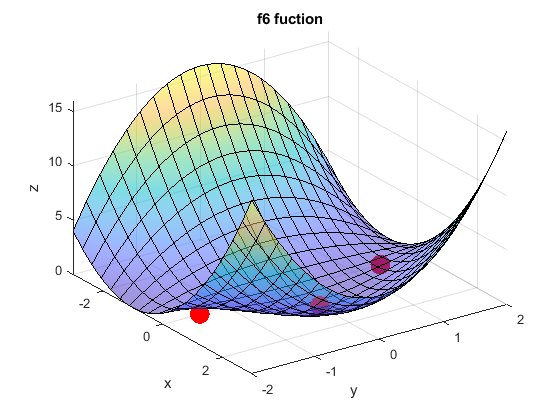

figure
fsurf(f6(x,y), [-3 3 -2 2], 'MeshDensity', 20); hold on
plot3(c.x, c.y, f5(c.x,c.y), 'ro', 'MarkerFaceColor', 'r',"MarkerSize",14 )
xlabel('x'); ylabel('y'); zlabel('z')
title('f6 fuction'); alpha 0.5
view(55,35)




syms x y LocMax LocMin Saddle Unknown real
f7(x,y)=x/(1+x.^2+y.^2)

$$f7(x, y) = \frac{x}{x^{2}+y^{2}+1}$$

grad_f7=gradient(f7,[x y])'

$$grad\_f7(x, y) = \left(\begin{array}{cc} \frac{1}{x^{2}+y^{2}+1}-\frac{2\,x^{2}}{{\left(x^{2}+y^{2}+1\right)}^{2}} & -\frac{2\,x\,y}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}\right)$$

hess=hessian(f7, [x,y]); H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} \frac{8\,x^{3}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{6\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} & \sigma_{1}\\ \sigma_{1} & \frac{8\,x\,y^{2}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{2\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,x^{2}\,y}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{2\,y}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}$$

LPMD(x,y)=[H(1,1), det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} \frac{8\,x^{3}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{6\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} & -\frac{4\,\left(x^{4}+2\,x^{2}\,y^{2}-3\,x^{2}+y^{4}+y^{2}\right)}{{\left(x^{2}+y^{2}+1\right)}^{5}} \end{array}\right)$$

c=solve(grad_f7==[0 0], [x y])

c = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


M = [c.x c.y], m=size(M,1)

$$M = \left(\begin{array}{cc} -1 & 0\\ 1 & 0 \end{array}\right)$$

m = 2

disp('x y f0 LPMD Type')

x y f0 LPMD Type


for k = 1:m
    xp = M(k,1); yp= M(k,2); P = [xp yp]; L = LPMD(xp , yp);
    if L(1)>0 && L(2)>0
        T=LocMin
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f0(xp,yp) L T];
    disp(r)
end

$$T = \mathrm{LocMin}$$

$$\left(\begin{array}{cccccc} -1 & 0 & 5 & \frac{1}{2} & \frac{1}{4} & \mathrm{LocMin} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 1 & 0 & 5 & -\frac{1}{2} & \frac{1}{4} & \mathrm{LocMax} \end{array}\right)$$

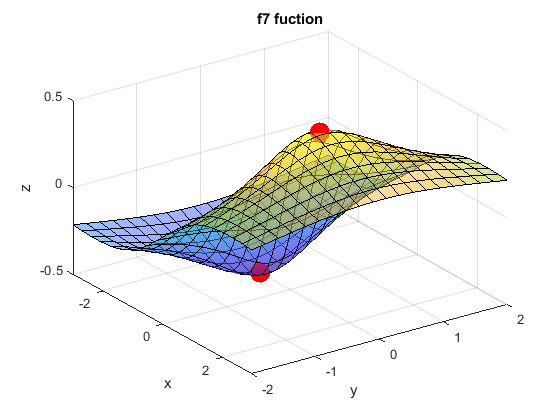

figure
fsurf(f7(x,y), [-3 3 -2 2], 'MeshDensity', 20); hold on
plot3(c.x, c.y, f7(c.x,c.y), 'ro', 'MarkerFaceColor', 'r',"MarkerSize",14 )
xlabel('x'); ylabel('y'); zlabel('z')
title('f7 fuction'); alpha 0.5
view(55,35)




syms x y LocMax LocMin Saddle Unknown real
f8(x,y)= (x-1)/(x^2+y^2)

$$f8(x, y) = \frac{x-1}{x^{2}+y^{2}}$$

grad_f8=gradient(f8,[x y])'

$$grad\_f8(x, y) = \left(\begin{array}{cc} \frac{1}{x^{2}+y^{2}}-\frac{2\,x\,\left(x-1\right)}{{\left(x^{2}+y^{2}\right)}^{2}} & -\frac{2\,y\,\left(x-1\right)}{{\left(x^{2}+y^{2}\right)}^{2}} \end{array}\right)$$

hess=hessian(f8, [x,y]); H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} \frac{8\,x^{2}\,\left(x-1\right)}{\sigma_{2}}-\frac{2\,\left(x-1\right)}{\sigma_{3}}-\frac{4\,x}{\sigma_{3}} & \sigma_{1}\\ \sigma_{1} & \frac{8\,y^{2}\,\left(x-1\right)}{\sigma_{2}}-\frac{2\,\left(x-1\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,x\,y\,\left(x-1\right)}{\sigma_{2}}-\frac{2\,y}{\sigma_{3}}\\ \sigma_{2}={\left(x^{2}+y^{2}\right)}^{3}\\ \sigma_{3}={\left(x^{2}+y^{2}\right)}^{2} \end{array}$$

LPMD(x,y)=[H(1,1), det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} \frac{8\,x^{2}\,\left(x-1\right)}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{2\,\left(x-1\right)}{{\left(x^{2}+y^{2}\right)}^{2}}-\frac{4\,x}{{\left(x^{2}+y^{2}\right)}^{2}} & -\frac{4\,\left(x^{2}-4\,x+y^{2}+3\right)}{{\left(x^{2}+y^{2}\right)}^{4}} \end{array}\right)$$

c=solve(grad_f8==[0 0], [x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M = [c.x c.y], m=size(M,1)

$$M = \left(\begin{array}{cc} 2 & 0 \end{array}\right)$$

m = 1

disp('x y f8 LPMD Type')

x y f8 LPMD Type


for k = 1:m
    xp = M(k,1); yp= M(k,2); P = [xp yp]; L = LPMD(xp , yp);
    if L(1)>0 && L(2)>0
        T=LocMin
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    else
        T=Unknown;
    end
    r=[P f8(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 2 & 0 & \frac{1}{4} & -\frac{1}{8} & \frac{1}{64} & \mathrm{LocMax} \end{array}\right)$$

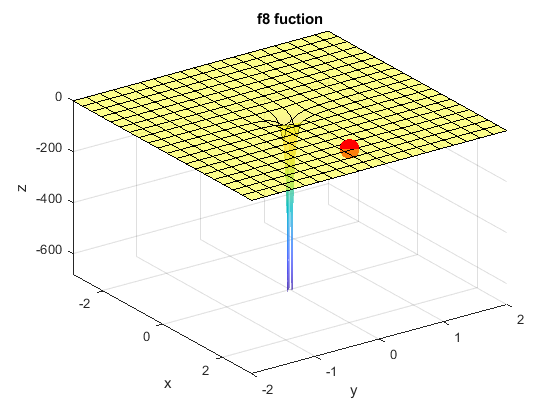

figure
fsurf(f8(x,y), [-3 3 -2 2], 'MeshDensity', 20); hold on
plot3(c.x, c.y, f8(c.x,c.y), 'ro', 'MarkerFaceColor', 'r',"MarkerSize",14 )
xlabel('x'); ylabel('y'); zlabel('z')
title('f8 fuction'); alpha 0.5
view(55,35)

# Ερώτημα 1.2

ii) Η εικόνα της f στο (0,0) είναι 0 και προκύπτει από τον πάνω κλάδο. Πέρνοντας τα όρια στο 0 προς τα δεξιά και αριστερά από τον δεύτερο και πρώτο κλάδο αντίστοιχα προκύπτουν διαφορετικές τιμές 1 και 0 αντίστοιχα.

Επομένως η συνάρτηση είναι μη συνεχής στο σημείο (0,0) καθώς δεν υπάρχει το όριο της f στο (0,0).

# Ερώτημα 1.3

syms x y
f(x,y) = sin(x^2+y^2)/(x^2+y^2)

$$f(x, y) = \frac{\sin\left(x^{2}+y^{2}\right)}{x^{2}+y^{2}}$$

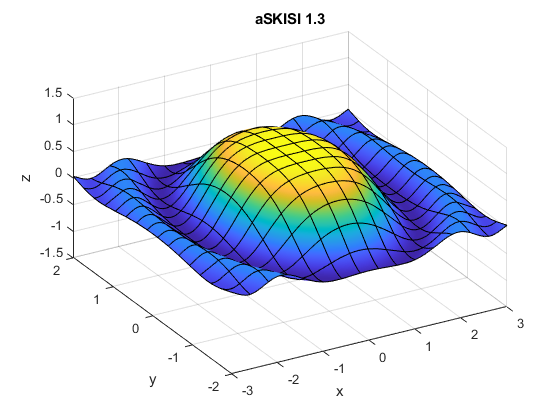

figure
fsurf(f, [-4 4 -4 4], 'MeshDensity', 16); hold on
plot3(0,0,0, 'mo', 'MarkerFaceColor', 'm', 'Markersize', 12)
xlabel('x'); ylabel('y'); zlabel('z')
xticks(-3:3); yticks(-2:2); zticks(-1.5:0.5:1.5)
axis([-3 3 -2 2 -1.5 1.5])
title('aSKISI 1.3')
view(-30,40)

Η συνάρτηση είναι f(x,y)=sin(x^2 + y^2)/x^2 + y^2 .

Από την συνάρτηση γνωρίζουμε οτι, οταν (x,y)->(0,0) τοτε το όριο της f είναι 1

Για τις πολικες συντεταγμενες εχουμε 

lim[f(x.y)] καθώς (x,y)->(0,0) είναι ίσο με 1 <=>

lim[sin(x^2 + y^2)/x^2 + y^2] καθώς (x,y)->(0,0) =

lim[sin(ρ^2cos^2θ+ρ^2sin^2θ)/ρ^2cos^2θ+ρ^2sin^2θ] καθώς (ρ,θ)->(0,0) =

lim[sin(ρ^2)/ρ^2]

Θα θέσουμε το ρ^2 = L

Επομένως lim[sin(L)/L] καθώς L->0 ειναι ίσο με 1

# Ερώτημα 1.4

syms ro theta
V = int(int(4*ro- ro^3*(cos(theta))^2-ro^3*(sin(theta))^2-((1-3*ro*cos(theta))-10*ro*sin(theta))/9 , ro, 2, 0), theta, 2*pi, 0)

$$V = \frac{68\,\pi }{9}$$